% https://www.mathworks.com/help/ident/ref/resid.html
cnc_params
filelistPP = ["Position_control_PP_29-Apr-2025_15-52-56.mat", "Position_control_PP_29-Apr-2025_15-57-33.mat", "Position_control_PP_29-Apr-2025_15-59-58.mat", "Position_control_PP_29-Apr-2025_16-05-57.mat", "Position_control_PP_29-Apr-2025_16-06-47.mat", "Position_control_PP_29-Apr-2025_16-08-04.mat", "Position_control_PP_29-Apr-2025_16-15-38.mat", "Position_control_PP_29-Apr-2025_16-19-46.mat", "Position_control_PP_29-Apr-2025_16-21-40.mat", "Position_control_PP_29-Apr-2025_16-27-10.mat", "Position_control_PP_29-Apr-2025_16-42-20.mat", "Position_control_PP_29-Apr-2025_16-47-32.mat", "Position_control_PP_29-Apr-2025_16-51-46.mat", "Position_control_PP_29-Apr-2025_16-53-53.mat", "Position_control_PP_29-Apr-2025_16-56-11.mat", "Position_control_PP_29-Apr-2025_17-06-15.mat", "Position_control_PP_29-Apr-2025_17-07-34.mat", "Position_control_PP_29-Apr-2025_17-09-36.mat", "Position_control_PP_29-Apr-2025_17-12-23.mat", "Position_control_PP_29-Apr-2025_17-24-13.mat", "Position_control_PP_29-Apr-2025_17-27-12.mat", "Position_control_PP_29-Apr-2025_17-36-36.mat", "Position_control_PP_29-Apr-2025_17-44-09.mat", "Position_control_PP_29-Apr-2025_17-52-13.mat", "Position_control_PP_29-Apr-2025_17-54-56.mat", "Position_control_PP_29-Apr-2025_17-57-36.mat", "Position_control_PP_29-Apr-2025_17-59-27.mat", "Position_control_PP_29-Apr-2025_18-02-38.mat", "Position_control_PP_29-Apr-2025_18-04-42.mat", "Position_control_PP_29-Apr-2025_18-07-34.mat", "Position_control_PP_29-Apr-2025_18-09-31.mat", "Position_control_PP_29-Apr-2025_18-15-12.mat", "Position_control_PP_29-Apr-2025_18-17-45.mat", "Position_control_PP_29-Apr-2025_18-21-45.mat", "Position_control_PP_29-Apr-2025_18-22-36.mat", "Position_control_PP_29-Apr-2025_18-25-08.mat", "Position_control_PP_29-Apr-2025_18-28-11.mat", "Position_control_PP_29-Apr-2025_18-31-08.mat", "Position_control_PP_29-Apr-2025_18-34-28.mat", "Position_control_PP_29-Apr-2025_18-35-20.mat", "Position_control_PP_29-Apr-2025_18-36-40.mat", "Position_control_PP_29-Apr-2025_18-39-17.mat", "Position_control_PP_29-Apr-2025_18-49-00.mat", "Position_control_PP_29-Apr-2025_18-51-45.mat", "Position_control_PP_29-Apr-2025_18-54-05.mat", "Position_control_PP_29-Apr-2025_18-55-32.mat", "Position_control_PP_29-Apr-2025_18-57-08.mat", "Position_control_PP_29-Apr-2025_18-59-52.mat"];

openLoopM0 = "lab6/data/PP/"+filelistPP([18 19 21]);
openLoopM1 =  "lab6/data/PP/"+filelistPP(22:23);

P0 = P_ext(1);
P1 = P_ext(2);

b21 = (k *r /Ra)/J_tilda;


A0 = [0 1 ; 
    0 -P0];
A1 = [0 1 ; 
    0 -P1];
B = [0 ; -b21];
C = [1 0];


% M = [0; 1/(J_tilda *eta_g *eta_m)]; % For torque disturbance
M = B; % For Volt disturbance


G0ss = ss(A0,B,C,0);
G1ss = ss(A1,B,C,0);


P0 = P_ext(1);
mu0 = mu_ext(1);
P1 = P_ext(2);
mu1 = mu_ext(2);
G0 = tf(-mu0,[1/P0 1 0]);
G1 = tf(-mu1,[1/P1 1 0]);

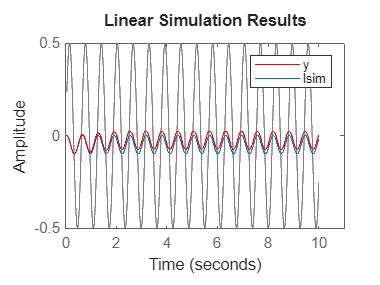

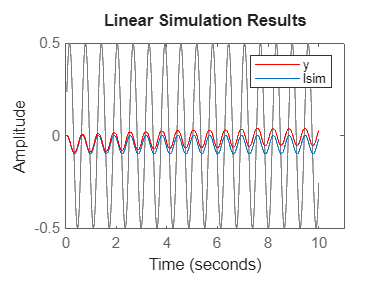

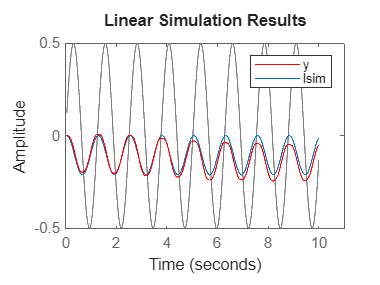

t = [];
y = [];
u = [];

idds = {};
opt = residOptions;
opt.MaxLag = 10;

idx_start = time2index(0.05);
idx_end = time2index(10);


for i=1:3
data = load(openLoopM0(i)).data;

t =  data(1,idx_start:idx_end)';
y =  data(2,idx_start:idx_end)';
u =  data(6,idx_start:idx_end)';

figure

plot(t,y,"r")
hold on
% plot(t,u)

lsim(0.807*G0ss,u,t)
hold off
legend(["y","lsim"])




 % idd = detrend(idd);
% plot(idd)
% plot(t,y);
% plot(t,u);

end